# Next Paper, Journal?

### TO DO

- degradation parameter std should start off large and then update based on the true system filters

- parallelize digitaltwin execution, gather total flight times, create distribution. this is RUL for next true system flight

### Load paths and variables

addpath(genpath(pwd));
load_fresh_workspace;
load_trajectory;
%init_simulation_params;

### Simulate

Mode Selection 

- true system - nominal

- true system - degraded

- digital twin - nominal

- digital twin - degraded

sys = "TrueSystem";
%sys = "DigitalTwin";

mode = "Nominal";
%mode = "Degraded";

% degraded_level needs fixed to reflect the non-accelerated degradation
% profiles, before 11 was really degraded, now it is hardly
degraded_level = 11;

Degraded or Nominal

if mode == "Degraded"
    battery.R0=rdeg(degraded_level);
    battery.Q=qdeg(degraded_level);
    Motor2.Req=mdeg(degraded_level);
    Motor4.Req=mdeg(degraded_level);
else
    battery.R0=rdeg(1);
    battery.Q=qdeg(1);
    Motor2.Req=mdeg(1);
    Motor4.Req=mdeg(1);
end

if sys == 'TrueSystem'
    octomodel.sampletime = .025;
    disp('true system simulation');
    load_system('truesystem');
    tic
    sim('truesystem.slx');
    toc
else
    batterytwin = battery;
    Motortwin2 = Motor2;
    Motortwin4 = Motor4;
    octomodel.sampletime = .05;
    load_system('digitaltwin1c');
    tic

true system simulation


Elapsed time is 229.979292 seconds.


    sim('digitaltwin1c.slx');

rul = 19.4500

    toc
end
rul = flight_time.Data(end)

## Plot Path

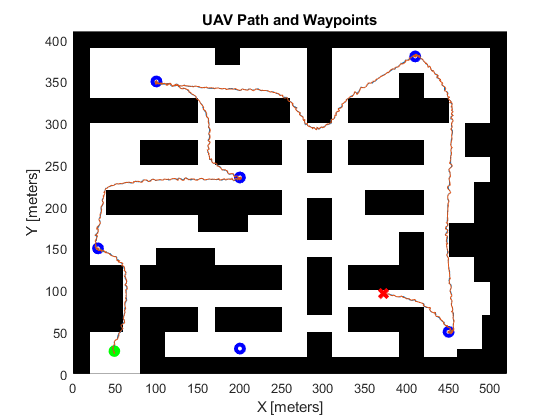

f1 = figure(1); clf;
hold on;
show(map);
plot(pos_observed.Data(1,1), pos_observed.Data(1,2), 'go', 'markerfacecolor', 'g', 'markersize', 8);
for i = 1:length(waypoints)
   plot(waypoints(i,1), waypoints(i,2), 'bo', 'LineWidth', 3); 
end
plot(pos_actual.Data(:,1), pos_actual.Data(:,2));
plot(pos_observed.Data(:,1), pos_observed.Data(:,2));
if ~any(stop_code.Data(:,3))
    plot(pos_observed.Data(end, 1), pos_observed.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3);

end
hold off;
title("UAV Path and Waypoints");

## Euclidean Position Error

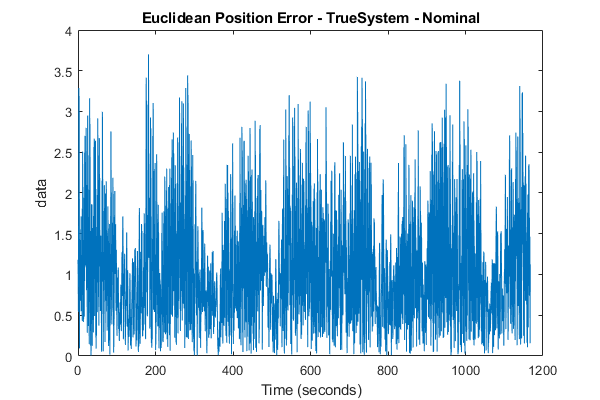

f2 = figure(2); clf;

plot(euclidean_pos_err);
ttl = sprintf("%s - %s - %s", 'Euclidean Position Error', sys, mode);
title(ttl);

## Voltage and SOC Plot

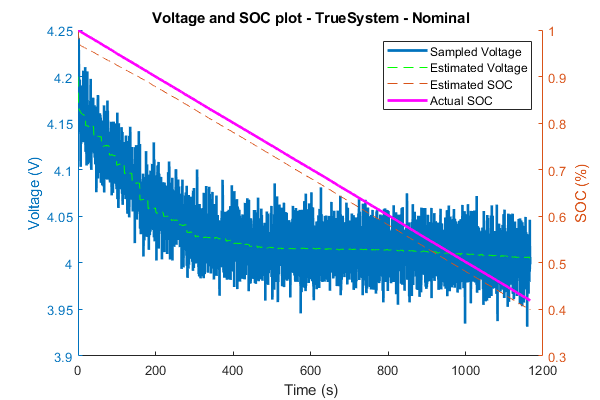

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
yyaxis left;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,1), 'linewidth', 2, "DisplayName", "Sampled Voltage");
plot(battery_actual.Time(:), battery_actual.Data(:,1), 'g', "DisplayName", "Estimated Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,2), '--', "DisplayName", "Estimated SOC");
plot(battery_actual.Time(:), battery_actual.Data(:,2),'m-', 'linewidth', 2, "DisplayName", "Actual SOC");
hold off;
ttl = sprintf("%s - %s - %s", 'Voltage and SOC plot', sys, mode);
title(ttl);

xlabel("Time (s)");
ylabel("SOC (%)");
legend();

## Current Plot

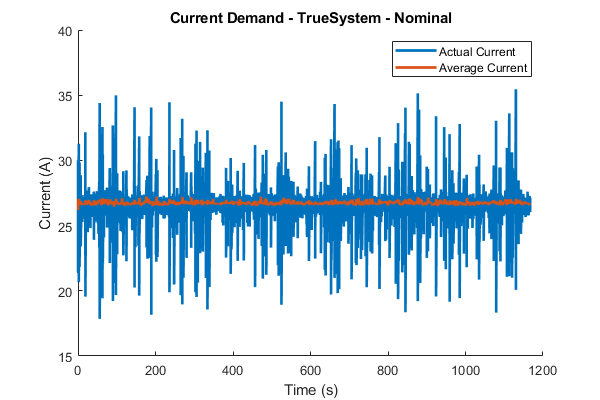

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
hold on;
plot(current_actual.Time(:,1), current_actual.Data(:,1), 'linewidth', 2, "DisplayName", "Actual Current");
plot(downsample(current_actual.Time(:,1), 5),smoothdata(downsample(current_actual.Data(:,1), 5), 'rlowess', 20), 'linewidth', 2, "DisplayName", "Average Current");
ttl = sprintf("%s - %s - %s", 'Current Demand', sys, mode);
title(ttl);
xlabel("Time (s)");

ylabel("Current (A)");

r0_var = 0.0022

Q_var = 0.9487

ylim([15 40]);
legend();


# *********************************************************************************************************************

# Scratch paper below

# *********************************************************************************************************************

## Simulation loop preparation

- run true system

- collect degradation parameter variance

addpath(genpath(pwd));
load_fresh_workspace;
load_trajectory;


i = 1;

Error evaluating registered method 'Outputs' of MATLAB S-Function 'Dynamics2' in 'truesystem/Airframe'.

Caused by:
    Error using next_paper (line 99)
    Program interruption (Ctrl-C) has been detected.

% loop 
octomodel.sampletime = true_sample_rate;
tic
sim('truesystem.slx');
toc
r_var = battery_observed.Data(end, 5)
q_var = battery_observed.Data(end, 7)
m_var = motors.Data(2, 4)

battery.R0 = normrnd(rdeg(i), r_var);
battery.Q = normrnd(qdeg(i), q_var);
Motor2.Req = normrnd(mdeg(i), m_var);

octomodel.sampletime = twin_sample_rate;
numRuns = 12;
tic
for i = 1:numRuns
    in(i) = Simulink.SimulationInput("digitaltwin1c");
end
tic
out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_workspace(i, r_var, q_var, m_var, twin_sample_rate));
toc
%end
for i = 1:numRuns
    times(i) = out(i).flight_time.Data(end);
    vs(i) = out(i).battery_actual.Data(end, 1);
    socs(i) = out(i).battery_actual.Data(end, 2);
    R0s(i) = out(i).battery_actual.Data(end, 3);
    Qs(i) = out(i).battery_actual.Data(end, 6);

   18.7100   18.7100   18.7100   20.5200   19.3267   20.5200   18.7100   21.2467   21.2467   18.7100   18.7100   21.0200



    ms(i) = out(i).motors.Data(end, 1);

    0.0034    0.0034    0.0034    0.0022    0.0000    0.0022    0.0034    0.0025    0.0025    0.0034    0.0034    0.0017



end

    0.4096    0.4096    0.4096    0.4064    0.4124    0.4064    0.4096    0.4085    0.4085    0.4096    0.4096    0.4096



   14.6368   14.6368   14.6368   15.9574   15.1873   15.9574   14.6368   16.5710   16.5710   14.6368   14.6368   16.4358



disp(times)

    3.9405    3.9405    3.9405    3.9691    4.0332    3.9691    3.9405    3.9634    3.9634    3.9405    3.9405    3.9851



disp(R0s)

    0.2435    0.2435    0.2435    0.2433    0.2406    0.2433    0.2435    0.2373    0.2373    0.2435    0.2435    0.2428



disp(socs)

avg_time = 19.6783

disp(Qs)
disp(vs)
disp(ms)
avg_time = sum(times)/length(times)


## Parallel Testing

- get average runtime of of iteration without parallelism

load_system('digitaltwin1c');
runs = 5;
tic
for i = 1:runs
    load_fresh_workspace;

rul = 19.6933

rul = 20.2633

rul = 19.9867

rul = 19.6600

rul = 20.1867

    octomodel.sampletime = .05;

t2 = 786.9818

    sim("digitaltwin1c.slx");

ans = 157.3964

    rul = flight_time.Data(end)
end
t2 = toc
t2/runs

Parallel testing with parameters in setup function

arg1 = .03;
%evalin('base', 'partest.m')
for i = 1:5

Analyzing and transferring files to the workers ...done.


    in(i) = Simulink.SimulationInput('simpartest');
end

out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()partest(867));

res = 872.5466

res = 870.1727

res = 842.8379

res = 872.0269

res = 868.6979

for i = 1:5
    res = out(i).res.Data(1,1)
   
end

numRuns = 6;
tic
for i = 1:numRuns
    in(i) = Simulink.SimulationInput("digitaltwin1c");
end
tic
out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_workspace(i, r_var, q_var, m_var));
toc


for i = 1:numRuns
    times(i) = out(i).flight_time.Data(end);
    vs(i) = out(i).battery_actual.Data(end, 1);
    socs(i) = out(i).battery_actual.Data(end, 2);
    R0s(i) = out(i).battery_actual.Data(end, 3);
    Qs(i) = out(i).battery_actual.Data(end, 6);
    ms(i) = out(i).motors.Data(end, 1);
end
disp(times)
disp(R0s)
disp(socs)
disp(Qs)
avg_time = sum(times)/length(times)




